disp("Start simulation of model")

Start simulation of model



%Initialise data and filter
load mpu9250new.mat sensorData 
Fs = 10;
acceleration = [sensorData.ax sensorData.ay sensorData.az]

acceleration =          0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
    0.0100         0    1.0100
    0.0100         0    1.0100


gyroscope = [sensorData.gx sensorData.gy sensorData.gz]

gyroscope =    -0.0400   -1.0100   -1.5200
   -0.0500   -0.9200   -1.0600
   -0.2700   -0.8200   -0.7400
   -0.3400   -1.0500   -0.5700
   -0.2800   -1.0500   -0.7100
   -0.2100   -0.9700   -0.5100
   -0.0900   -0.6500   -0.5200
   -0.3900   -0.8900   -0.6200
   -0.4500   -1.1700    0.1800
   -0.6300   -1.2300   -0.3400


magnetometer = [sensorData.mx sensorData.my sensorData.mz]

magnetometer =   -37.6500   61.2600   -5.2300
  -38.3500   60.2200   -4.2200
  -36.6000   60.9100   -4.8900
  -36.0800   60.7400   -3.0400
  -36.6000   60.2200   -5.2300
  -36.7800   60.0400   -6.7500
  -36.6000   59.8700   -4.8900
  -37.6500   61.9600   -5.9000
  -37.3000   60.5600   -4.2200
  -37.8300   61.7900   -5.4000


decim = 1;
time = (0:decim:size(acceleration,1)-1)/Fs

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


fuse = ahrsfilter("SampleRate", 10, "DecimationFactor", decim);
limit = size(time, 2);

% calculate position
acceleration(:,3) = acceleration(:,3) - 1.0100

acceleration =          0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
    0.0100         0         0
    0.0100         0         0


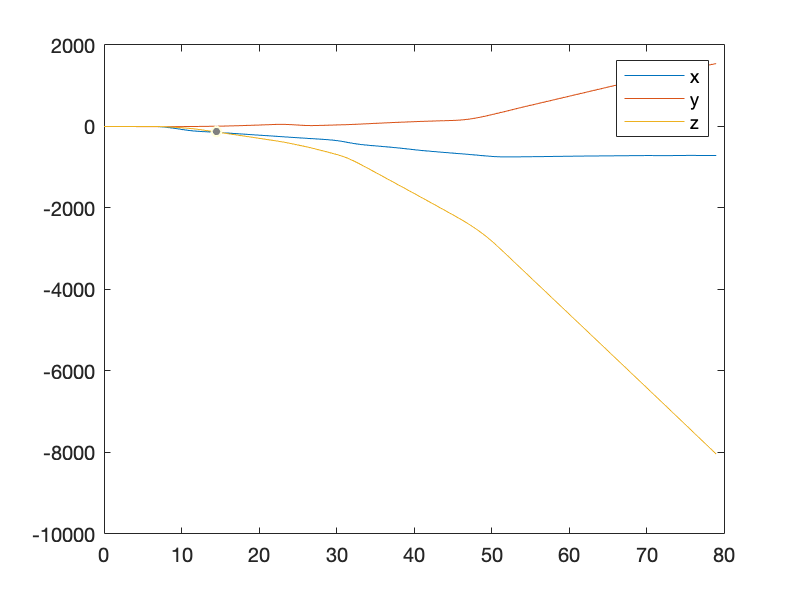

acceleration(:,:) = acceleration(:,:).*9.81; 
velocity = zeros(length(acceleration), 3);
for i = 2:length(acceleration) 
        velocity(i,:) = velocity(i-1,:) + (acceleration(i,:)+acceleration(i-1,:))/(2*Fs);
end

position = zeros(length(velocity), 3);
for i = 2:length(velocity) 
        position(i,:) = position(i-1,:) + (velocity(i,:)+velocity(i-1,:))/(2*Fs);
end

plot(time', position(:,:))
legend("x","y","z")

%initialise pose plot
pp = poseplot

pp =   PosePatch with properties:

    Orientation: [1×1 quaternion]
       Position: [0 0 0]

  Show all properties


xlabel("North-x (m)")
ylabel("East-y (m)")
zlabel("Down-z (m)");
xlim([-50.00 50.00])
ylim([-50.00 50.00])
zlim([-50.00 50.00])
pos = [0 0 0];

%Create orientation matrix
for i = 1:limit
    q = fuse(acceleration(i, :), gyroscope(i, :), magnetometer(i, :));
    pos = position(i,:);
    set(pp, Orientation = q, Position = pos);
    drawnow
end

%Start reading values and then fuse them
%c = size(time, 2)
%for i = 1:c
 %   q = fuse(acceleration(i, :), gyroscope(i, :), magnetometer(i, :));
  %  plot(time(i), eulerd(q, "ZYX", "frame"), "MarkerSize", 20);
%end
